## **The Top of Your Code Document:**

If you would like to make a reproducible analysis pipeline, I recommend including several things at the top of your analysis code documents:

**1) Your name and the date that you completed the analysis (+ any edits, updates). **

Christian did this earlier by using the "%" symbol to comment out his code:

% Sample_dataset_1_code
% C Burgess
% 190701

Within a "Live editor" document, you can do the same thing by inserting a section of text using the drop-down menu ( "Live editor"->"Text"):

"Updated by Megan Hagenauer, 08/17/2019"

***      Add your own name and the date here:***

%

**2) A brief description of the goals of the analysis:**

We are adding on to the "Sample_dataset_1_code" that we produced earlier as part of Neuroscience Bootcamp. Our goal is to make our previous analysis a little bit closer to the workflow necessary to produce a publishable result for a Nature journal using the new data analysis and visualization recommendations. 

**3) Record the version of Matlab that you are using and which toolboxes you have installed:**

You can access this information using the command:

ver

-----------------------------------------------------------------------------------------------------
MATLAB Version: 9.6.0.1150989 (R2019a) Update 4
MATLAB License Number: 820543
Operating System: Mac OS X  Version: 10.12.6 Build: 16G2128 
Java Version: Java 1.8.0_181-b13 with Oracle Corporation Java HotSpot(TM) 64-Bit Server VM mixed mode
-----------------------------------------------------------------------------------------------------
MATLAB                                                Version 9.6         (R2019a)
Bioinformatics Toolbox                                Version 4.12        (R2019a)
Optimization Toolbox                                  Version 8.3         (R2019a)
Signal Processing Toolbox                             Version 8.2         (R2019a)
Statistics and Machine Learning Toolbox               Version 11.5        (R2019a)
Symbolic Math Toolbox                                 Version 8.3         (R2019a)


-----------------------------------------------------------------------------------------------------

MATLAB Version: 9.6.0.1150989 (R2019a) Update 4

MATLAB License Number: 820543

Operating System: Mac OS X  Version: 10.12.6 Build: 16G2128 

Java Version: Java 1.8.0_181-b13 with Oracle Corporation Java HotSpot(TM) 64-Bit Server VM mixed mode

-----------------------------------------------------------------------------------------------------

MATLAB                                                Version 9.6         (R2019a)

Bioinformatics Toolbox                                Version 4.12        (R2019a)

Optimization Toolbox                                  Version 8.3         (R2019a)

Signal Processing Toolbox                             Version 8.2         (R2019a)

Statistics and Machine Learning Toolbox               Version 11.5        (R2019a)

Symbolic Math Toolbox                                 Version 8.3         (R2019a)

## **Reading in the Data:**

You can read in the data by using the drop-down menus ("Home"->"Open") and navigating to the folder where you downloaded the original dataset, which was stored as a Matlab file: "Sample_data_1_bootcamp_dataset.mat"

However, in the future you will probably be reading in your data from a spreadsheet (e.g. Excel). So I made a version of this dataset in Excel:

 "Sample_data_1_bootcamp_dataset.xlsx"

1) Go to the tab on the far upper left labeled "Home" and choose the "Import Data" icon

- Navigate to your local folder containing  "Sample_data_1_bootcamp_dataset.xlsx"

2)  In the pop-up window: 

- Matlab guesses that you would like to call the object Sampledata1bootcampdataset. This is a stupidly long name. Let's rename it "Sampledata1".

- Matlab guesses which data types you have in each column, but sometimes is incorrect. Double check the data types listed under each variable - *which one is incorrect?*  You can fix incorrect data types by clicking on the adjacent drop down arrow.

- *What would happen if you organized your spreadsheet so that the data for each variable was in a row instead of a column?*

- Note that the variable names are defined by Row 1 by default, but this can be changed if necessary. 

- If everything looks good, select all of the data in the matrix and click on the icon in the far right corner that says "Import data". *What happens if you accidentally select the row that includes the original column names during the import?*

## **Before Exploring the Data:**

Make some decisions about how you are going to perform the analysis. This makes it less likely to introduce a hiddent multiple comparisons problem by running the analysis multiple ways, and then choosing one version to present.

**1) What will be your definition of an outlier sample?**

    Example definitions:

- >3 standard deviations from the mean for a group.

- Outside the whiskers of a boxplot for a group.

**2) What is your primary outcome? (main hypothesis)**

    I hypothesize that there is a sex difference in tail_length that is mediated by a sex difference in body mass.

**3) What test will you use to examine your primary outcome?**

I will use the linear regression model:

tail_length ~ mass + sex

**4) What results would support your hypothesis?**

When using a simple t-test, I expect to see a significant relationship beween tail_length and sex as well as between tail_length and mass.

When using the larger regression model, I expect to see a significant relationship between tail_length and mass but not between tail_length and sex. This model will also show an effect size for sex that is negligible. 

**Note:** The last two steps are less important for the analysis of this dataset because there are so few variables.

## **Exploring the Data:**

The object Sampledata1 should now be in your workspace to the left. The "Value" tells you more about its properties (20x4 table).

**1) Calculate some summary statistics to see your sample size per group and a basic overview:**

summary(Sampledata1)


Variables:

    RatID: 20×1 categorical

        Values:

            1        1   
            10       1   
            11       1   
            12       1   
            13       1   
            14       1   
            15       1   
            16       1   
            17       1   
            18       1   
            19       1   
            2        1   
            20       1   
            3        1   
            4        1   
            5        1   
            6        1   
            7        1   
            8        1   
            9        1   

    Sex: 20×1 categorical

        Values:

            f     10  
            m     10  

    Mass: 20×1 double

        Values:

            Min          23 
            Median     28.5 
            Max          34 

    Tail_length: 20×1 double

        Values:

            Min            82      
            Median         88      
            Ma

*What is the sample size per group?*

**2) Make a histogram for your numeric data:**

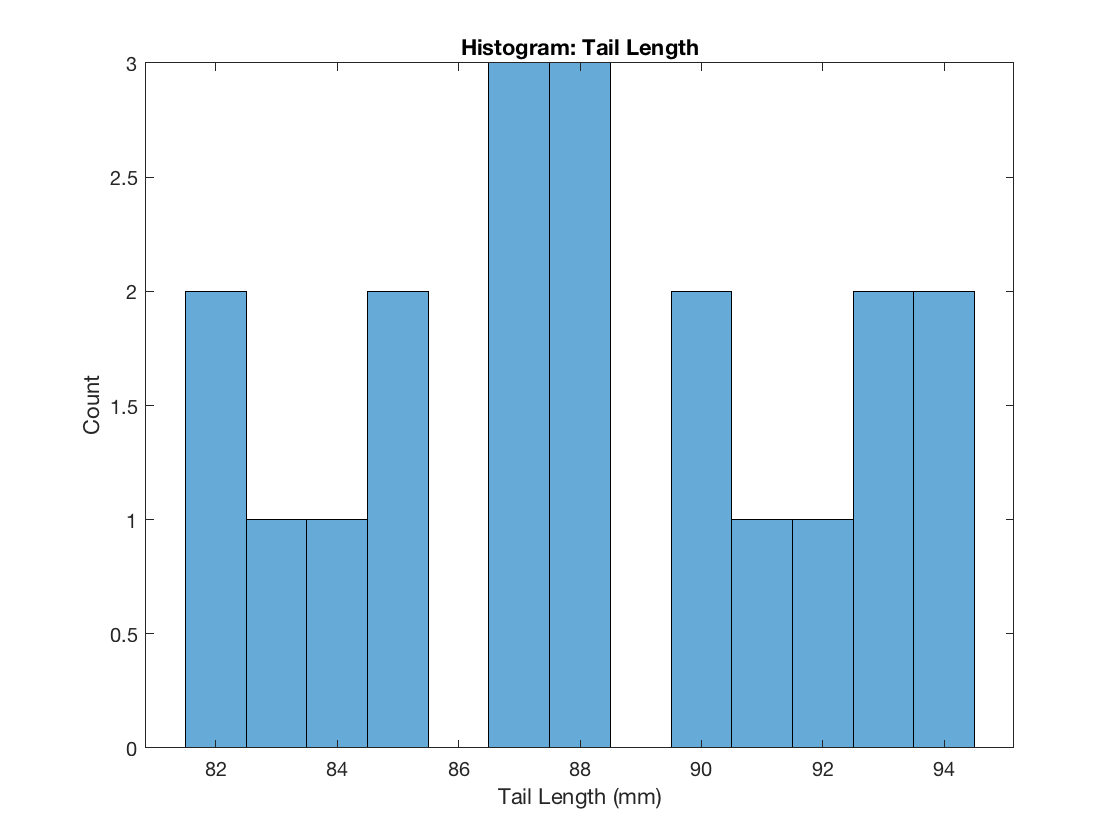

%You can make a simple histogram using:
histogram(Sampledata1.Tail_length)
title("Histogram: Tail Length")
xlabel("Tail Length (mm)")
ylabel("Count")

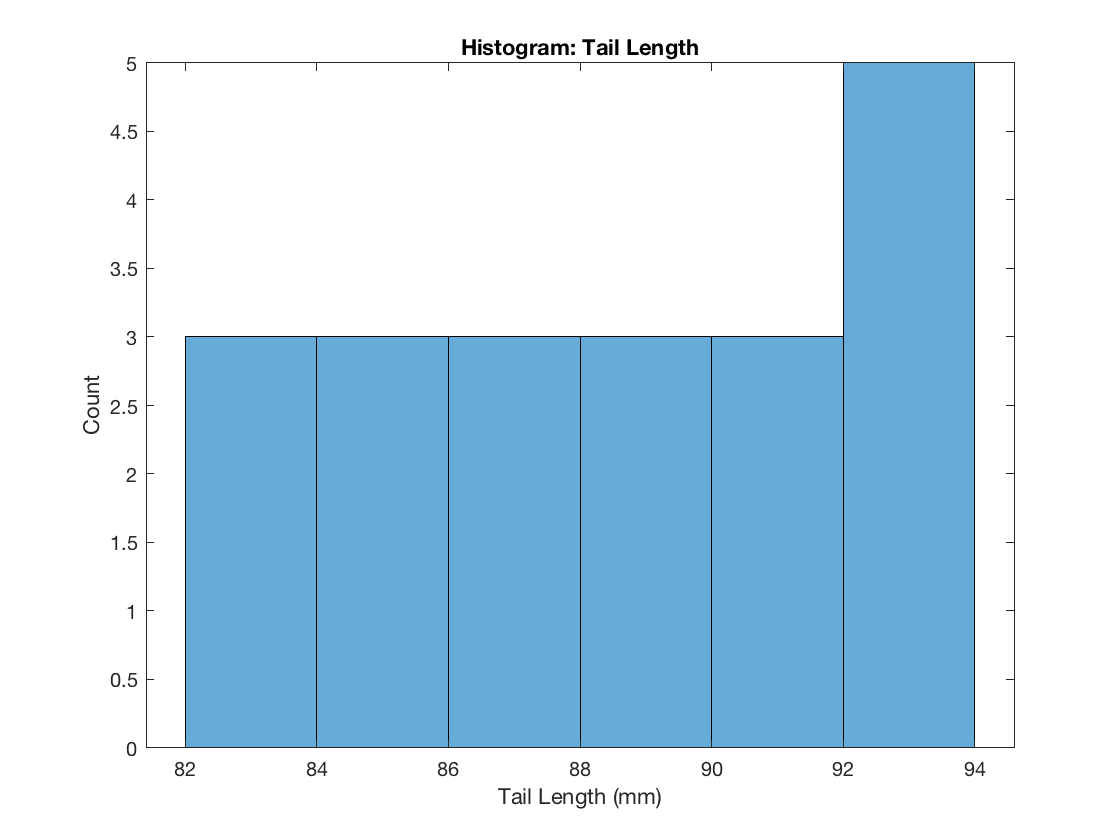


%...but bin width matters. I recommend trying several bin widths, e.g.:

%with 6 bins:
histogram(Sampledata1.Tail_length,6)
title("Histogram: Tail Length")
xlabel("Tail Length (mm)")
ylabel("Count")

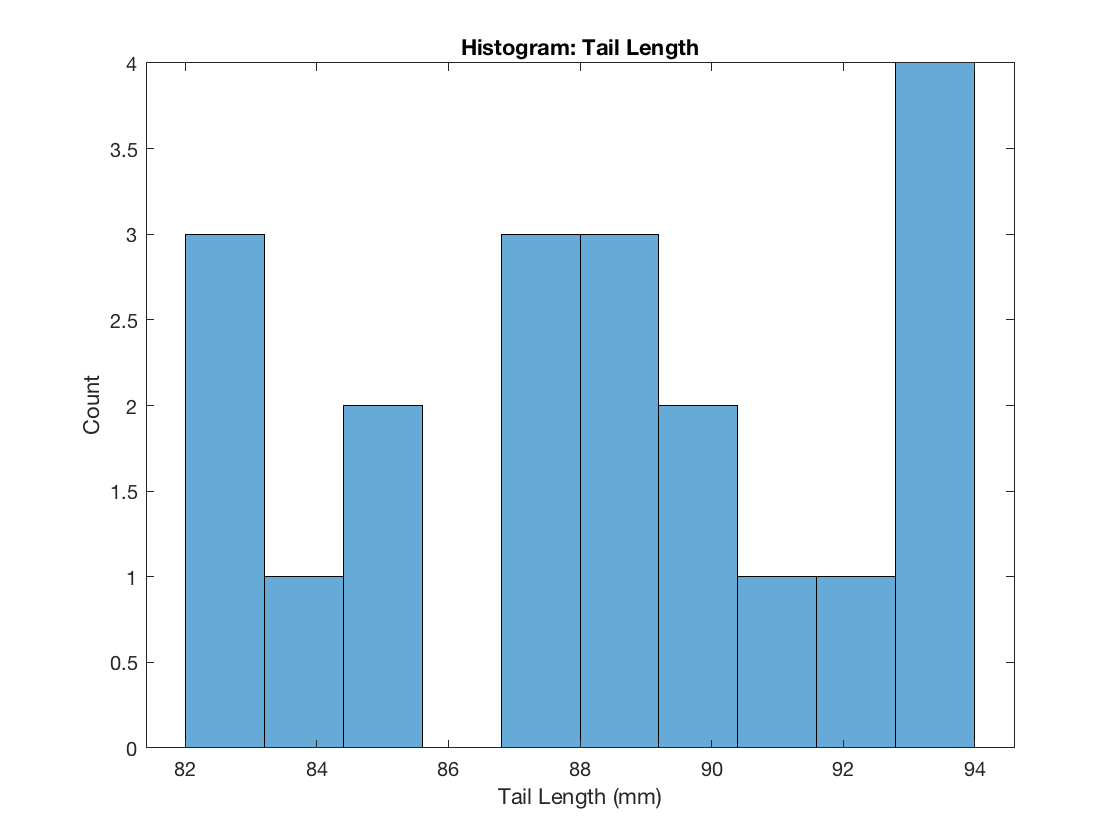


%with 10 bins:
histogram(Sampledata1.Tail_length,10)
title("Histogram: Tail Length")
xlabel("Tail Length (mm)")
ylabel("Count")

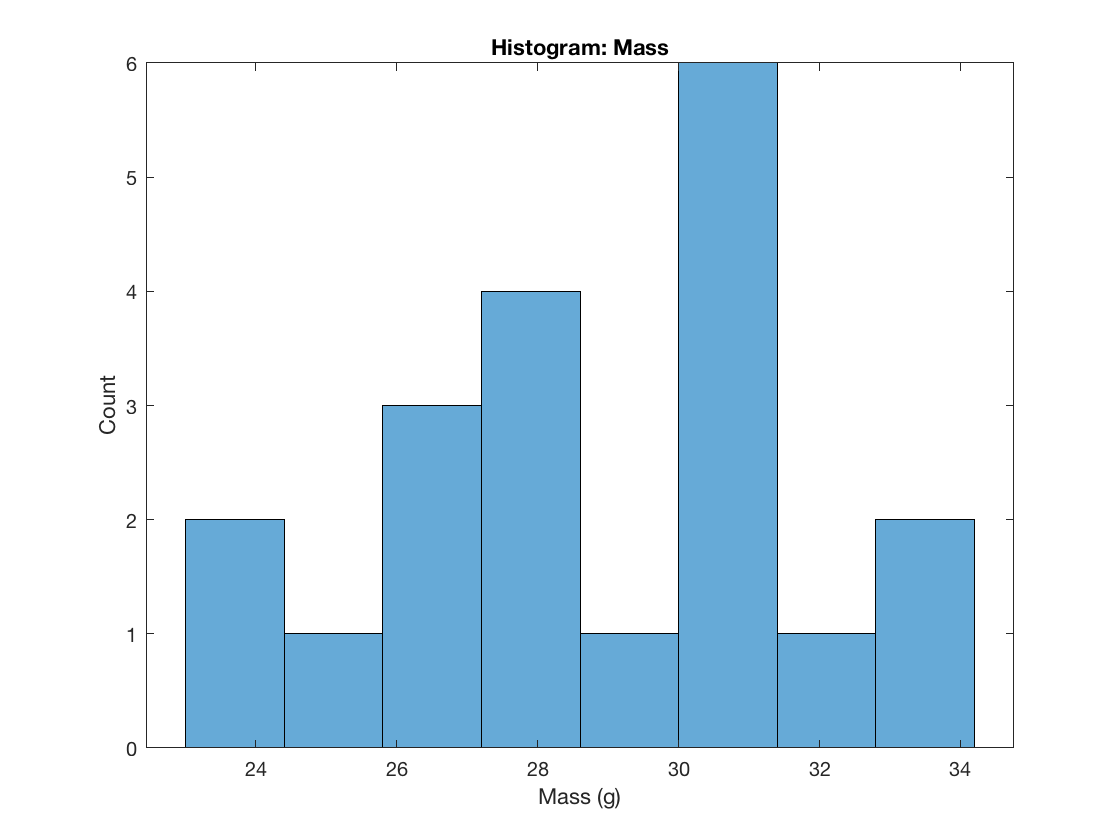

% What might be a good rule for determining how many bins to use?


histogram(Sampledata1.Mass,8)
title("Histogram: Mass")
xlabel("Mass (g)")
ylabel("Count")

*Does your data seem normally distributed? *

*Do you feel confident that you can determine the shape of the distribution in this sample size?*

**3) Examine the distribution in each group: Boxplot**

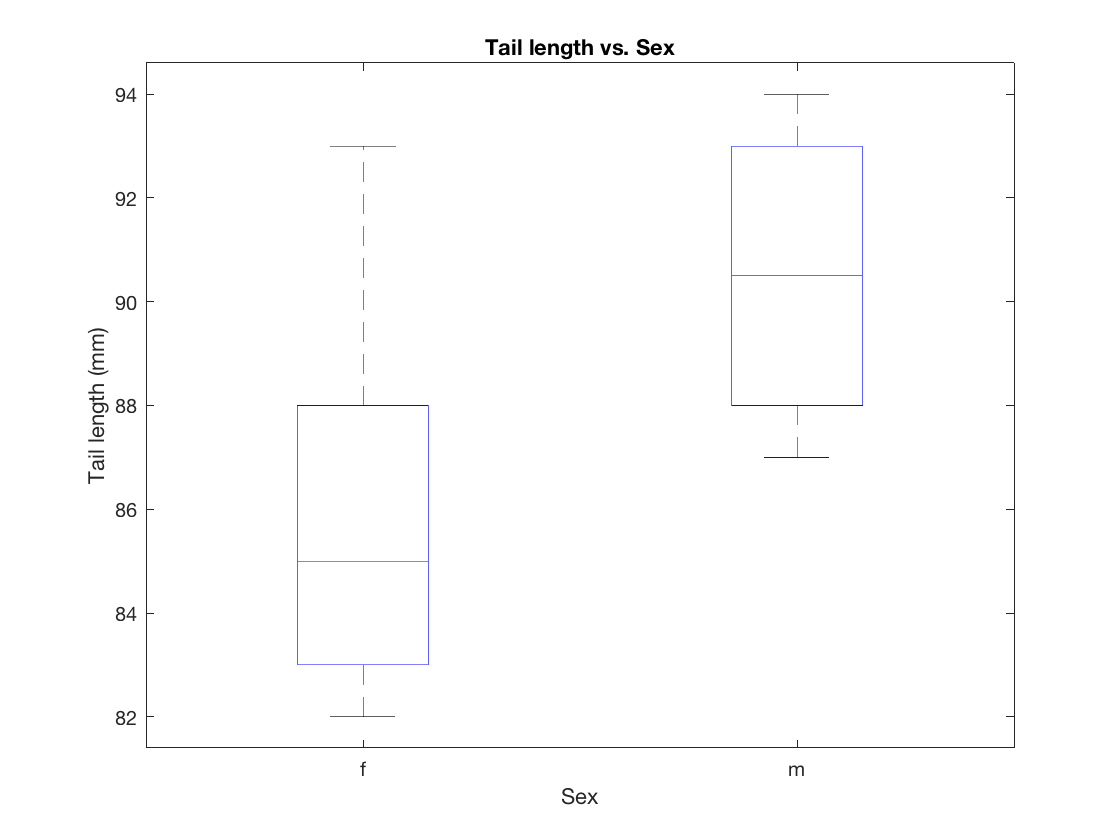

boxplot(Sampledata1.Tail_length, Sampledata1.Sex);
title("Tail length vs. Sex")
xlabel("Sex")
ylabel("Tail length (mm)")

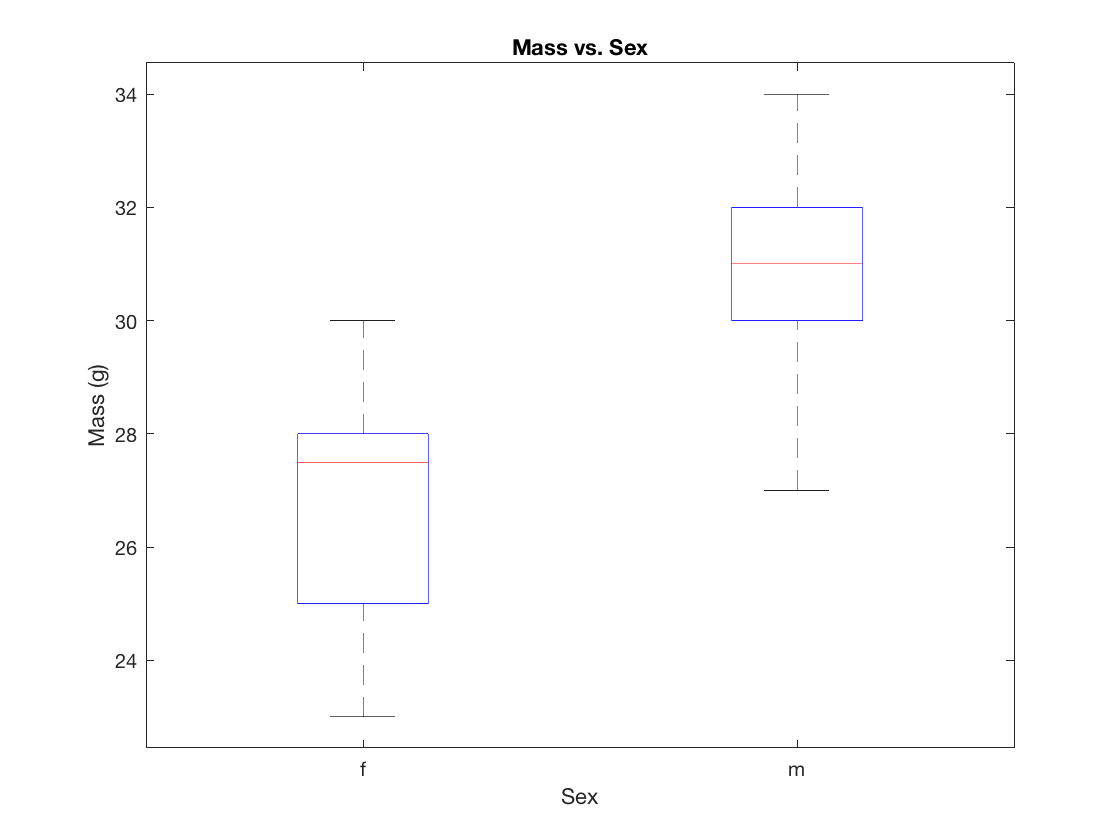


boxplot(Sampledata1.Mass, Sampledata1.Sex);
title("Mass vs. Sex")
xlabel("Sex")
ylabel("Mass (g)")

*Do you see any outliers?*

**4) Examine the distribution in each group: Violin plot**

Matlab does not include a function for making violing plots in its toolboxes. Therefore, to make a violin plot you first need to download code from the file exchange:

https://www.mathworks.com/matlabcentral/fileexchange/45134-violin-plot

If you unzip the file, and open it in Matlab, Matlab will prompt you to place the file in the Matlab file path.

After that, the function should be available for you to use.

%the first argument is a cell array [] 
%it contains the data subsetted by sex
FemaleTailLength=Sampledata1.Tail_length(Sampledata1.Sex=="f")

FemaleTailLength =     88
    84
    87
    83
    82
    85
    82
    85
    93
    88


MaleTailLength=Sampledata1.Tail_length(Sampledata1.Sex=="m")

MaleTailLength =     93
    88
    87
    92
    87
    94
    94
    90
    90
    91



ForViolinPlot=[FemaleTailLength MaleTailLength]

ForViolinPlot =     88    93
    84    88
    87    87
    83    92
    82    87
    85    94
    82    94
    85    90
    93    90
    88    91



%the second argument specifies the x-axis labels
%the third argument changes the color
violin(ForViolinPlot,'xlabel',{'f','m'},'facecolor',[[1 0 0];[0 0 1]])

ans =   1×2 Patch array:

    Patch    Patch


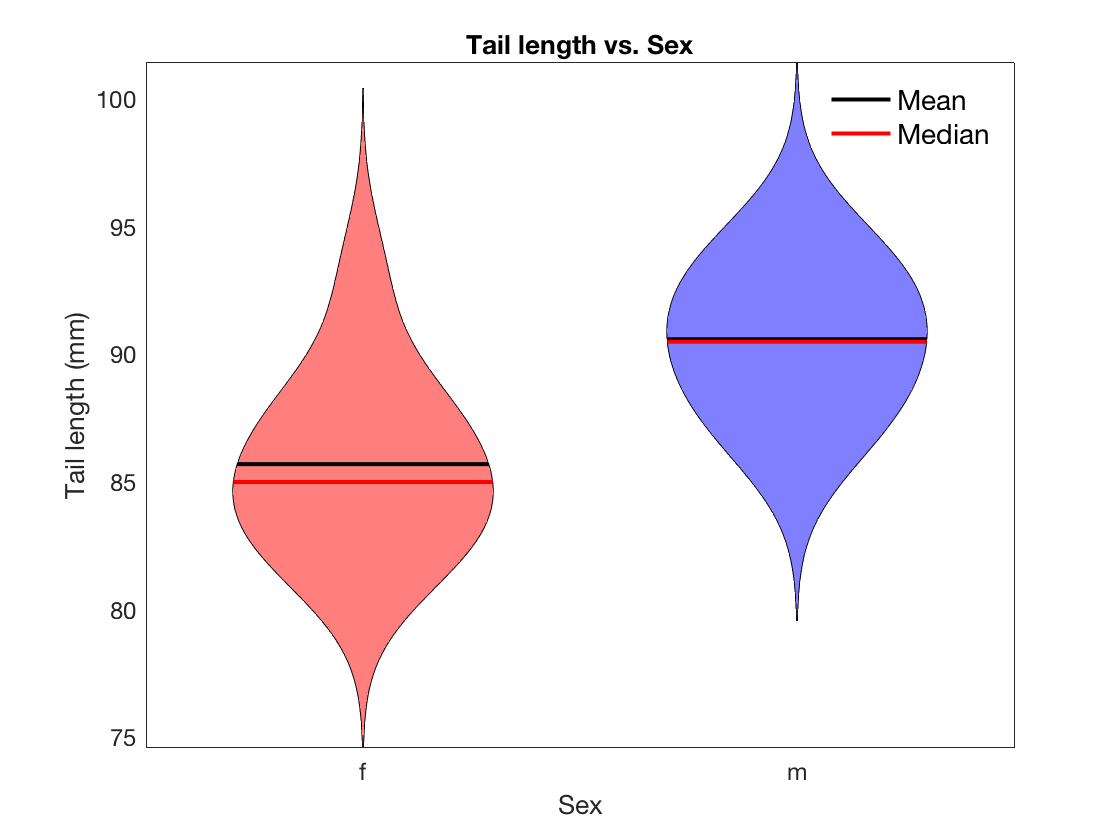

title("Tail length vs. Sex")
xlabel("Sex")
ylabel("Tail length (mm)")
hold off


FemaleMass=Sampledata1.Mass(Sampledata1.Sex=="f")

FemaleMass =     28
    26
    29
    23
    25
    27
    24
    28
    30
    28


MaleMass=Sampledata1.Mass(Sampledata1.Sex=="m")

MaleMass =     32
    34
    27
    28
    30
    31
    33
    31
    31
    30



ForViolinPlot2=[FemaleMass MaleMass]

ForViolinPlot2 =     28    32
    26    34
    29    27
    23    28
    25    30
    27    31
    24    33
    28    31
    30    31
    28    30



violin(ForViolinPlot2,'xlabel',{'f','m'},'facecolor',[[1 0 0];[0 0 1]])

ans =   1×2 Patch array:

    Patch    Patch


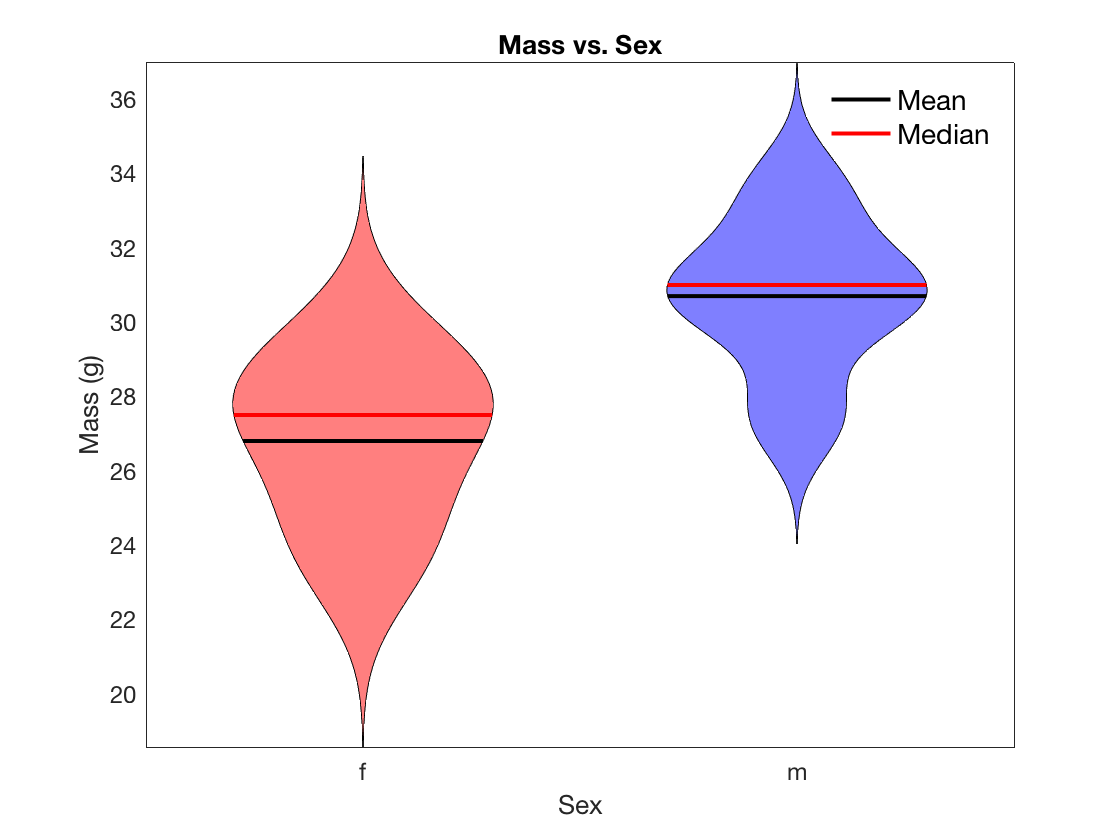

title("Mass vs. Sex")
xlabel("Sex")
ylabel("Mass (g)")
hold off

* Does your data look approximately normally distributed in each group?*

## Visualize relationship between tail length and mass

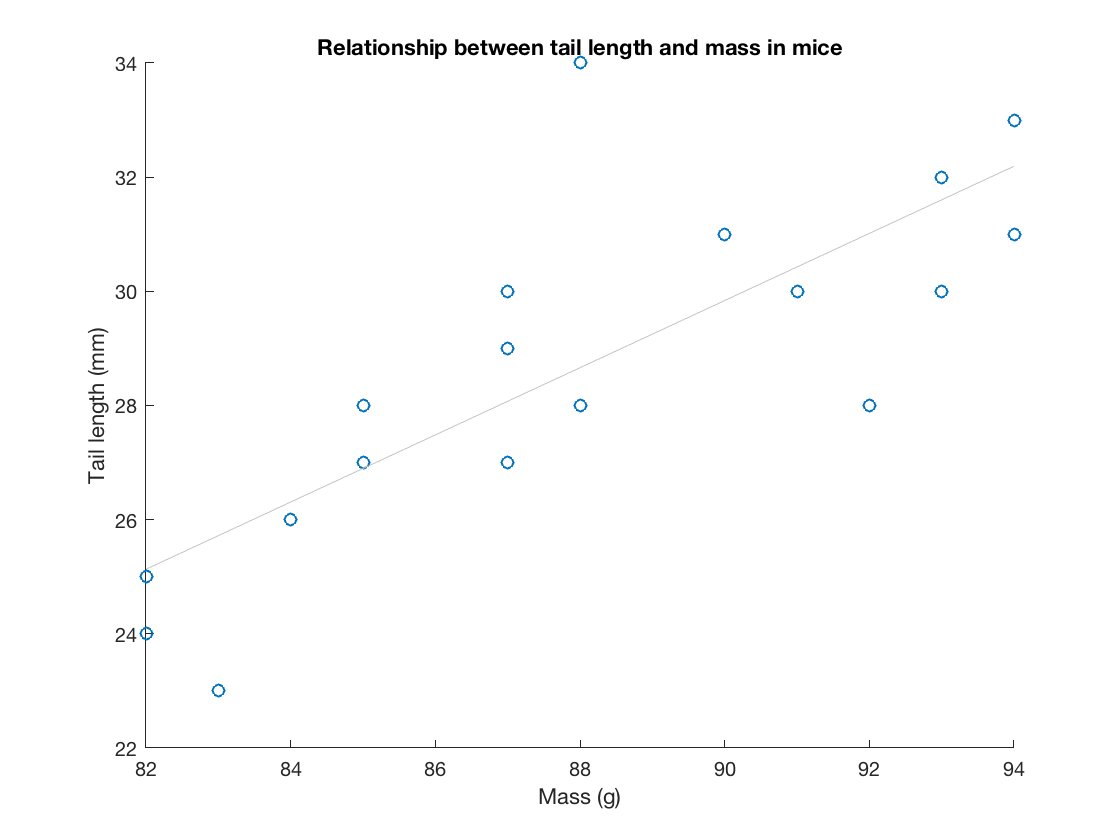

%Plotting just the basic relationship between Tail Length & Mass

% use a scatter plot
scatter(Sampledata1.Tail_length,Sampledata1.Mass);

%add labels to axes and a title
ylabel('Tail length (mm)')
xlabel('Mass (g)')
title('Relationship between tail length and mass in mice')

%add a line of best fit
lsline

hold off

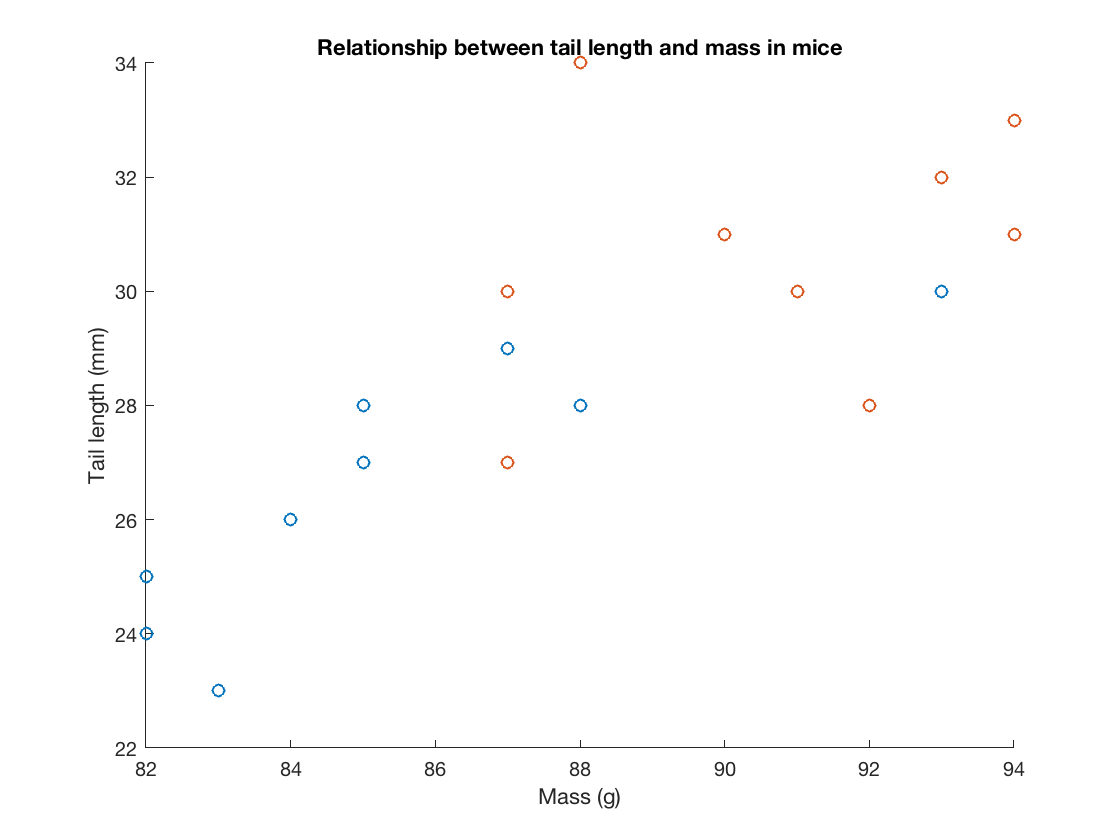



%Plotting a scatterplot with separate lines for males and females

scatter(Sampledata1.Tail_length(Sampledata1.Sex=="f"),Sampledata1.Mass(Sampledata1.Sex=="f"));
hold on
scatter(Sampledata1.Tail_length(Sampledata1.Sex=="m"),Sampledata1.Mass(Sampledata1.Sex=="m"));

%add labels to axes and a title
ylabel('Tail length (mm)')
xlabel('Mass (g)')
title('Relationship between tail length and mass in mice')
hold off


%Does it look like the relationship between Mass and Tail Length is the
%same in males and females?

%Does it look like there is a sex difference in tail length that is
%independent of the sex difference in mass?

## Reporting Central Tendency and Variation

**1) Calculate average mass and tail_length by sex**

%separate tail length into males and females
Tail_length_males=Sampledata1.Tail_length(Sampledata1.Sex=='m');
Tail_length_females=Sampledata1.Tail_length(Sampledata1.Sex=='f');

%calculate means
mean_taillength_males=mean(Tail_length_males)

mean_taillength_males = 90.6000

mean_taillength_females=mean(Tail_length_females)

mean_taillength_females = 85.7000


%separate mass into males and females
mass_males=Sampledata1.Mass(Sampledata1.Sex=='m');
mass_females=Sampledata1.Mass(Sampledata1.Sex=='f');

%calculate means
mean_mass_males=mean(mass_males)

mean_mass_males = 30.7000

mean_mass_females=mean(mass_females)

mean_mass_females = 26.8000

**2) Calculate the standard deviation for mass and tail_length by sex**

%calculate standard deviation
std_taillength_males=std(Tail_length_males)

std_taillength_males = 2.6750

std_taillength_females=std(Tail_length_females)

std_taillength_females = 3.4010


%calculate standard deviation
std_mass_males=std(mass_males)

std_mass_males = 2.1108

std_mass_females=std(mass_females)

std_mass_females = 2.2509

## Determining the 95% confidence intervals for the mean

**1) Traditional: Using a theoretical T-distribution:**

%Calculate standard error:

%You can use the length function to determine how many values are in a
%vector
SampleSize_males=length(mass_males)

SampleSize_males = 10

SampleSize_females=length(mass_females)

SampleSize_females = 10


%standard error = standard deviation / square root of n
ste_taillength_males = std_taillength_males/sqrt(SampleSize_males)

ste_taillength_males = 0.8459

ste_taillength_females = std_taillength_females/sqrt(SampleSize_females)

ste_taillength_females = 1.0755


ste_mass_males = std_mass_males/sqrt(SampleSize_males)

ste_mass_males = 0.6675

ste_mass_females = std_mass_females/sqrt(SampleSize_females)

ste_mass_females = 0.7118


% Calculate the degrees of freedom for the T-distribution
df_males=SampleSize_males-1

df_males = 9

df_females=SampleSize_females-1

df_females = 9


% Calculate 95% Probability Intervals Of t-Distribution
CI95_males= tinv([0.025 0.975], df_males)

CI95_males =    -2.2622    2.2622


CI95_females= tinv([0.025 0.975], df_females)

CI95_females =    -2.2622    2.2622



%The Confidence Interval is the Mean +/- the Critical T value*SE
CI95_males_mass=mean_mass_males+(CI95_males*ste_mass_males)

CI95_males_mass =    29.1900   32.2100


CI95_females_mass=mean_mass_females+(CI95_females*ste_mass_females)

CI95_females_mass =    25.1898   28.4102



CI95_males_taillength=mean_taillength_males+(CI95_males*ste_taillength_males)

CI95_males_taillength =    88.6864   92.5136


CI95_females_taillength=mean_taillength_females+(CI95_females*ste_taillength_females)

CI95_females_taillength =    83.2671   88.1329


**2) Using simulation (Bootstrapping)**

%the first argument is the number of simulated samples
%the second argument is the statistic you wish to compute on each sample
%the third argument is the data
CI95_bootstrap_males_mass=bootci(1000, @mean, mass_males)
CI95_bootstrap_females_mass=bootci(1000, @mean, mass_females)

CI95_bootstrap_males_taillength=bootci(1000, @mean, Tail_length_males)

CI95_bootstrap_males_taillength =    89.0000
   92.1622


CI95_bootstrap_females_taillength=bootci(1000, @mean, Tail_length_females)

CI95_bootstrap_females_taillength =    84.1031
   88.5632


## Calculating the effect size for the sex differences

**1) The unstandardized effect size is just the difference between the means**

mass_effectsize=mean_mass_males-mean_mass_females

mass_effectsize = 3.9000

taillength_effectsize=mean_taillength_males-mean_taillength_females

taillength_effectsize = 4.9000

**2) The standardized effect size is Cohen's D**

Cohen's D is just the difference between the means (the unstandardized effect size) divided by their pooled standard deviation. 

There is not a function in the Matlab toolbox to compute this, but you can download one here:

[https://www.mathworks.com/matlabcentral/fileexchange/62957-computecohen_d-x1-x2-varargin](https://www.mathworks.com/matlabcentral/fileexchange/62957-computecohen_d-x1-x2-varargin)

After downloading, unzip the file, open it in Matlab and try to run it. Matlab will then prompt you to place it in Matlab's file path. 

mass_cohensd=computeCohen_d(mass_males, mass_females,'independent')

mass_cohensd = 1.7874

taillength_cohensd=computeCohen_d(Tail_length_males, Tail_length_females,'independent')

taillength_cohensd = 1.6015

## Determining the significance of the sex differences:

**1) Examining group differences:  t-test**

%For mass:
[h,p,ci,stats]  = ttest(mass_males,mass_females)

h = 1

p = 0.0040

ci =     1.6017
    6.1983


stats = struct with fields:
    tstat: 3.8386
       df: 9
       sd: 3.2128



%For tail-length:
[h,p,ci,stats]  = ttest(Tail_length_males, Tail_length_females)

h = 1

p = 0.0066

ci =     1.7465
    8.0535


stats = struct with fields:
    tstat: 3.5150
       df: 9
       sd: 4.4083


*Using an alpha of 0.05, would these p-values be considered significant?*

**2) Examining group differences in tail-length while controlling for mass: linear regression**

Sampledata1.Sex

ans = 20×1 categorical array
     m 
     m 
     f 
     f 
     m 
     f 
     f 
     f 
     f 
     m 
     f 
     f 
     m 
     m 
     f 
     m 
     m 
     f 
     m 
     m 


%Sex needs to be converted to a dummy variable
DummySex=dummyvar(Sampledata1.Sex)

DummySex =      0     1
     0     1
     1     0
     1     0
     0     1
     1     0
     1     0
     1     0
     1     0
     0     1


%The first column has males as the reference group (0)
%The second column has females as the reference group (0)

%Specify the two predictor variables as a matrix
Predictors=[Sampledata1.Mass, DummySex(:,1)];

%Output the results from the regression model
fitlm(Predictors, Sampledata1.Tail_length)

ans = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)      64.02      8.2498     7.7602    5.5102e-07
    x1             0.86581     0.26751     3.2366     0.0048502
    x2             -1.5233      1.5215    -1.0012       0.33077


Number of observations: 20, Error degrees of freedom: 17
Root Mean Squared Error: 2.48
R-squared: 0.639,  Adjusted R-Squared: 0.596
F-statistic vs. constant model: 15, p-value = 0.000175

The estimates are the coefficients (betas) from the model. These are the unstandardized effect sizes.

*What does the intercept mean in this case?*

*What does x1 estimate mean?*

*What does x2 estimate mean?*

*As an example, let's calculate the average tail-length for a few example mice:*

%For a male mouse of 29 g:
64.02+(0.86*29)+0

ans = 88.9600


%For a male mouse of 32 g:
64.02+(0.86*32)+0

ans = 91.5400


%For a female mouse of 29 g:
64.02+(0.86*29)-1.52

ans = 87.4400


%How much of a difference is this compared to tail length at average mass? 
%Mean mass
mean_mass=mean(Sampledata1.Mass)

mean_mass = 28.7500

EffectofSex_AsPercent=(1.52/(64.02+(0.86*mean_mass)+0))*100

EffectofSex_AsPercent = 1.7128

**Going back to the regression output:**

*Do tail-length and mass still show a significant relationship in a model that controls for sex?*

*Do tail-length and sex still show a significant relationship in a model that controls for mass?*

*We hypothesized that the relationship between tail-length and sex would be mediated by mass - does it seem like that relationship is supported by our results?*

*Which statistic provides the best support for that conclusion - p-value or effect size (estimate)?*

*(i.e. can you conclude an absence of relationship if you see a p>0.05?)*